Pan axis 

syms W L V_y V_x d x_0 t theta_pan theta_dot_pan H a b c theta_tilt_sym theta_tilt_real

s      = [W  L  V_y V_x d theta_pan theta_dot_pan H];
s_real = [20 40 0   30  2 theta_pan theta_dot_pan 7];


x = (V_x * t - 1/2 * L);
y = (d + 1/2 * W);

theta_pan_sym = atan( x / y )

$$theta\_pan\_sym = -\mathrm{atan}\left(\frac{\frac{L}{2}-V_{x}\,t}{\frac{W}{2}+d}\right)$$

theta_dot_pan_sym = diff(theta_pan_sym)

$$theta\_dot\_pan\_sym = \frac{V_{x}}{\left(\frac{{\left(\frac{L}{2}-V_{x}\,t\right)}^{2}}{{\left(\frac{W}{2}+d\right)}^{2}}+1\right)\,\left(\frac{W}{2}+d\right)}$$

t_max_sym = L/V_x

$$t\_max\_sym = \frac{L}{V_{x}}$$



theta_pan_real = subs(theta_pan_sym, s, s_real)

$$theta\_pan\_real = \mathrm{atan}\left(\frac{5\,t}{2}-\frac{5}{3}\right)$$

theta_dot_pan_real = subs(theta_dot_pan_sym, s, s_real)

$$theta\_dot\_pan\_real = \frac{5}{2\,\left(\frac{{\left(30\,t-20\right)}^{2}}{144}+1\right)}$$

t_max = double(subs(t_max_sym, s, s_real))

t_max = 1.3333

theta_pan = @(time) subs(theta_pan_real, t, time);
theta_dot_pan = @(time) subs(theta_dot_pan_real, t, time);
t_vals = 0:0.01:t_max

t_vals =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


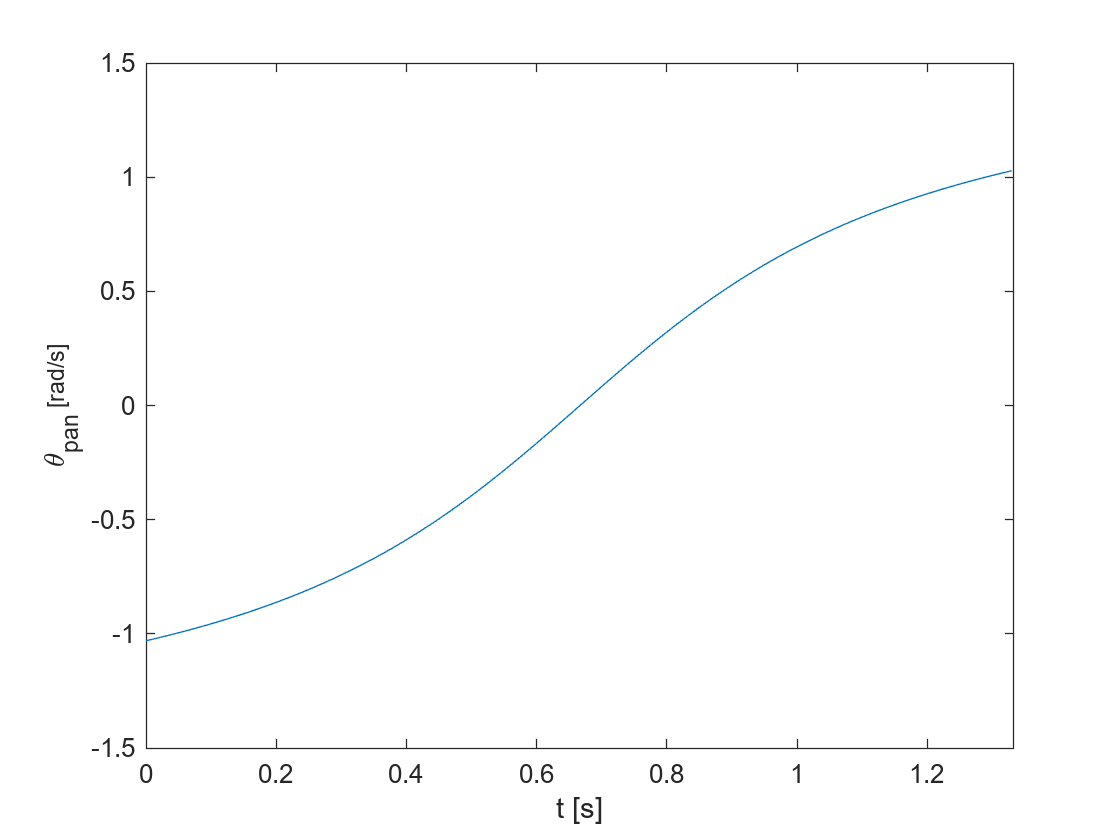

plot(t_vals, theta_pan(t_vals))
xlim([0 t_max])
xlabel('t [s]')
ylabel('\theta_{pan} [rad/s]')
exportgraphics(gcf, 'figures/reference_theta_pan.png')

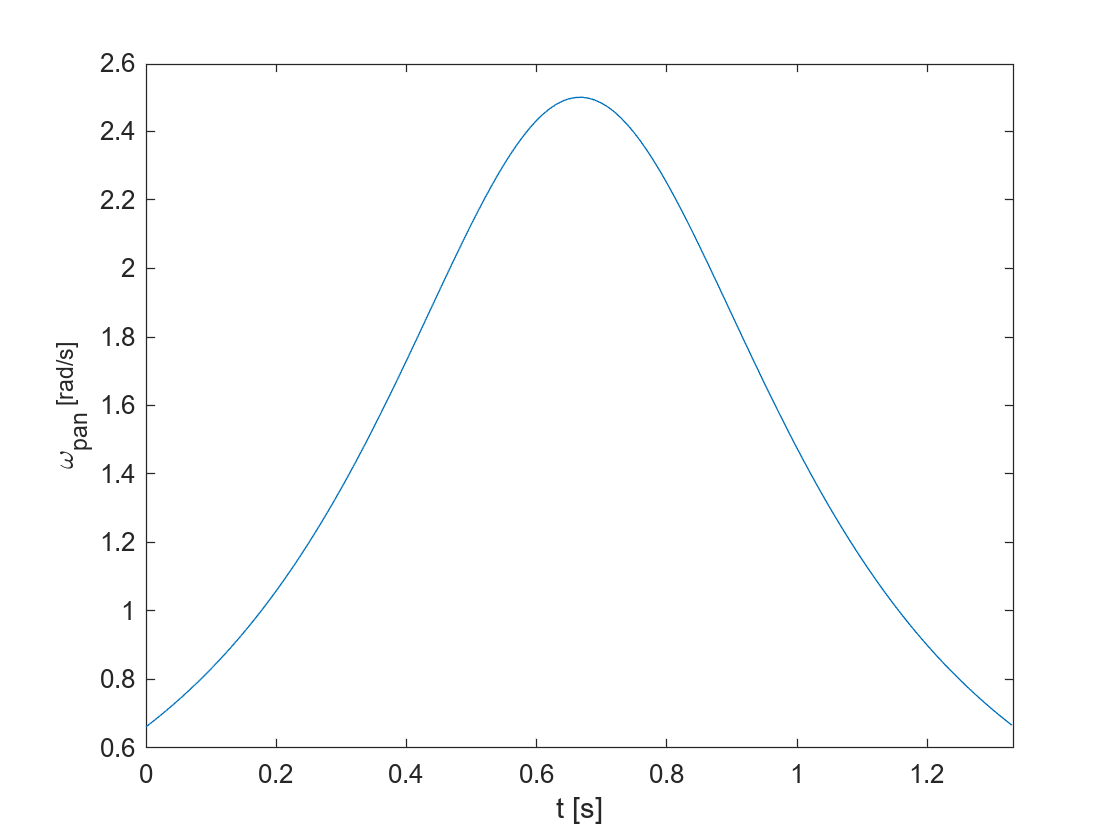


plot(t_vals, theta_dot_pan(t_vals))
xlim([0 t_max])
xlabel('t [s]')
ylabel('\omega_{pan} [rad/s]')
exportgraphics(gcf, 'figures/reference_omega_pan.png')

## Tilt axis

syms H a b c

z = @(t) a*t^2 + b*t + c;

eqs = [
    z(0) == 0;
    z(t_max/2) == H;
    z(t_max) == 0;
]

$$eqs = \left(\begin{array}{c} c=0\\ \frac{4\,a}{9}+\frac{2\,b}{3}+c=H\\ \frac{16\,a}{9}+\frac{4\,b}{3}+c=0 \end{array}\right)$$


[A B] = equationsToMatrix(eqs, [a b c])

$$A = \left(\begin{array}{ccc} 0 & 0 & 1\\ \frac{4}{9} & \frac{2}{3} & 1\\ \frac{16}{9} & \frac{4}{3} & 1 \end{array}\right)$$

$$B = \left(\begin{array}{c} 0\\ H\\ 0 \end{array}\right)$$

sol = solve(eqs, [a b c])

sol = struct with fields:
    a: -(9*H)/4
    b: 3*H
    c: 0


sol.a

$$ans = -\frac{9\,H}{4}$$



sol = subs(sol, s, s_real)

sol = struct with fields:
    a: -63/4
    b: 21
    c: 0



z = sol.a * t.^2 + sol.b * t + sol.c

$$z = 21\,t-\frac{63\,t^{2}}{4}$$

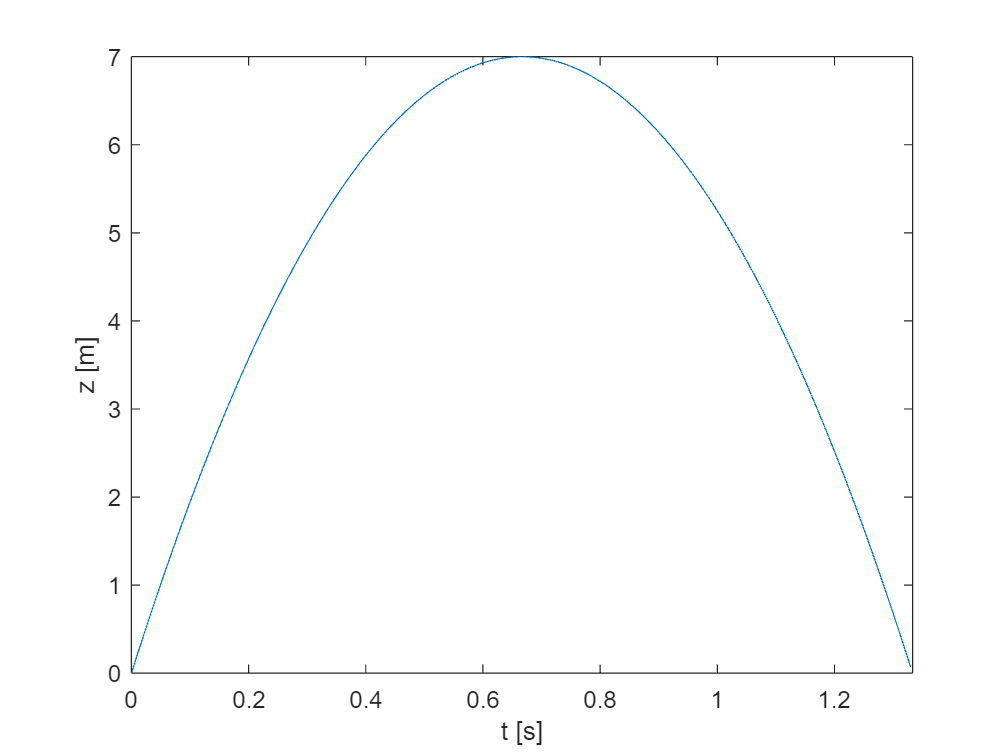

plot(t_vals, subs(z, t, t_vals))
xlim([0 t_max])
xlabel('t [s]')
ylabel('z [m]')

d = sqrt(x^2 + y^2)

$$d = \sqrt{{\left(\frac{L}{2}-V_{x}\,t\right)}^{2}+{\left(\frac{W}{2}+d\right)}^{2}}$$


theta_tilt_sym  = atan(z/d)

$$theta\_tilt\_sym = \mathrm{atan}\left(\frac{21\,t-\frac{63\,t^{2}}{4}}{\sqrt{{\left(\frac{L}{2}-V_{x}\,t\right)}^{2}+{\left(\frac{W}{2}+d\right)}^{2}}}\right)$$

theta_tilt = subs(theta_tilt_sym, [s], [s_real])

$$theta\_tilt = \mathrm{atan}\left(\frac{21\,t-\frac{63\,t^{2}}{4}}{\sqrt{{\left(30\,t-20\right)}^{2}+144}}\right)$$

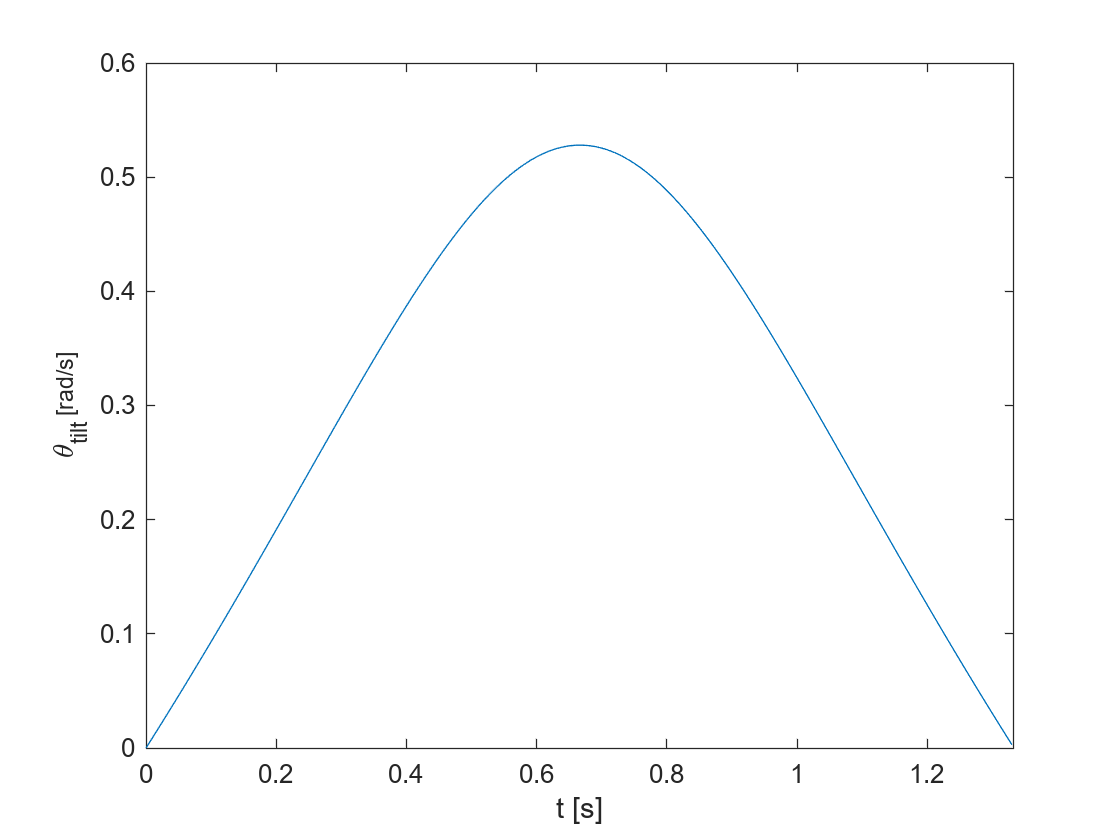

theta_tilt_real = subs(theta_tilt, t, t_vals);

theta_dot_tilt = diff(theta_tilt);
theta_dot_tilt_real = subs(theta_dot_tilt, t, t_vals);

plot(t_vals, theta_tilt_real)
xlim([0 t_max])
xlabel('t [s]')
ylabel('\theta_{tilt} [rad/s]')
exportgraphics(gcf, 'figures/reference_theta_tilt.png')

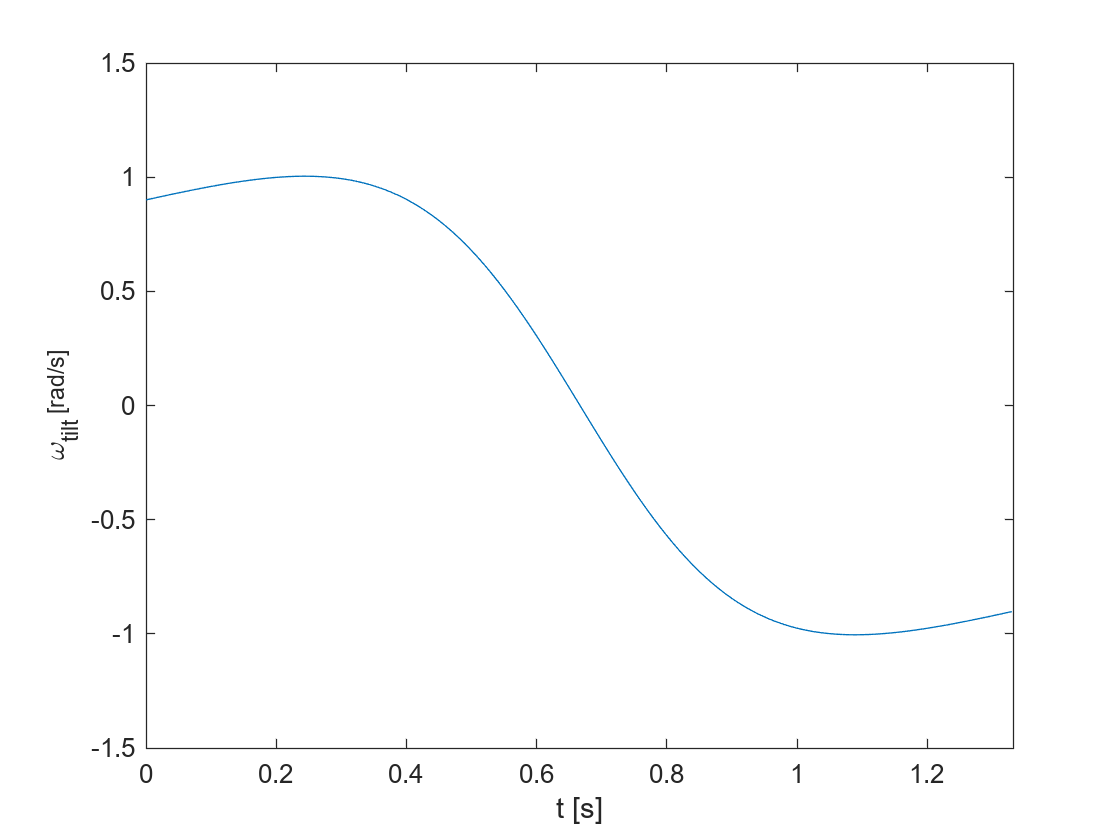


plot(t_vals, theta_dot_tilt_real)
xlim([0 t_max])
xlabel('t [s]')
ylabel('\omega_{tilt} [rad/s]')
exportgraphics(gcf, 'figures/reference_omega_tilt.png')